[trainimages trainlabels] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',60000 ,0);

[images labels] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',10000 ,0);

# K-meams + scaling

[https://abpaudel.com/blog/mnist-sequence-feature-extraction/](https://abpaudel.com/blog/mnist-sequence-feature-extraction/)

[features]  = extractfeatureswithHOG(trainimages(:,:,1:100),[4 4]);
features = [features trainlabels(1:100,:)];

[features]  = extractfeatureswithfourier(trainimages(:,:,1:10000), 44);
features = [features trainlabels(1:10000,:)];


[features]  = extractfeatureswithHarrisCorner(trainimages(:,:,1:10000), 100, 'BRISK');
features = [features trainlabels(1:10000,:)];
im()

# Fast-Fourier(Características de contorn) 

- Invariante a la rotación

- Invariante a la translación

- Variante al escalado

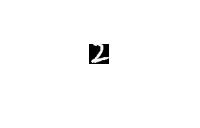

im2 = 20×20 logical array
   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0


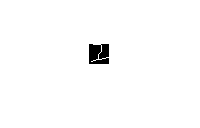

function [features] = extractfeatureswithfourier(images,Ndescriptors)
    [~, ~, nimages] = size(images);

    features = zeros(nimages, Ndescriptors);
    for i = 1:nimages
        im = images(:,:,i);
        features(i,:) = descriptor_fourier(im, Ndescriptors);
    end
end

function [descriptor] = descriptor_fourier(im, Ndescriptors)
    [d1 d2 d3] = size(im);
    im = imbinarize(im);
    im = imresize(im, [300 300]);
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    descriptor=fft(s);
    % Obtenim el 
    if (~isnan(Ndescriptors))
        descriptor = descriptor(1:Ndescriptors);
    end
    descriptor = log(abs(descriptor));
    descriptor = descriptor';
end

# HOG Features(Histogram of oriented gradients)

[https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html](https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html)

Bueno con machine learning SVM

- Invariante a la rotació (shifted the histogram)

- Invariante al escalado (try diferents scales of the image)

- Invariante a la translación.

function [features] = extractfeatureswithHOG(images, cellSize)
    im = images(:,:,1);
    im = imbinarize(im);
    im = imresize(im, [28 28]);
    hogFeatureSize = length(extractHOGFeatures(im, 'CellSize', cellSize));
    [~, ~, nimages] = size(images);
    features = zeros(nimages, hogFeatureSize);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        im = imresize(im, [28 28]);
        [feature image] = extractHOGFeatures(im, 'CellSize', cellSize);
        features(i,:) = feature;
    end
end

# Wavelet Scattering

- Variante a la translacion

- Variante al escalado

- Variante a la rotacion

[https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html](https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html)

function [features] = extractfeatureswithWaveletScattering(images)
    sf = waveletScattering2('ImageSize', [28 28]);
    [~, ~, nimages] = size(images);
    for i = 1:nimages
        im = imresize(images(:,:,i),[28 28]);
        if (i == 1)
           feature  = helperScatImages(sf,im);
           l = length(feature);
           features = zeros(nimages, l);
           features(1,:) = feature';
        else
            features(i,:)  = helperScatImages(sf,im)';
        end
    end
end
function features = helperScatImages(sf,x)
% This function is only to support examples in the Wavelet Toolbox.
% It may change or be removed in a future release.
% Copyright 2018 MathWorks
    smat = featureMatrix(sf,x,'transform','log');
    features = mean(mean(smat,2),3);
end

# Number of Corners (Harris Corner Detector)

function [features] = extractfeatureswithHarrisCorner(images, Nstrongest, Method)
    [~, ~, nimages] = size(images);
    im = imbinarize(images(:,:,1));
    corners =  detectHarrisFeatures(im);
    %[feature, ~] = extractFeatures(im,corners.selectStrongest(Nstrongest), 'Method',Method);
    %features = zeros(nimages, size(feature))
    features = zeros(nimages, 1);
    features(1,:) = length(corners);
    for i = 2:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        corners =  detectHarrisFeatures(im);
        features(i,:) = length(corners);
        %features(i,:) = extractFeatures(im,corners.selectStrongest(Nstrongest), 'Method',Method);
    end    
end